# Lecture 19

## Exercise 7

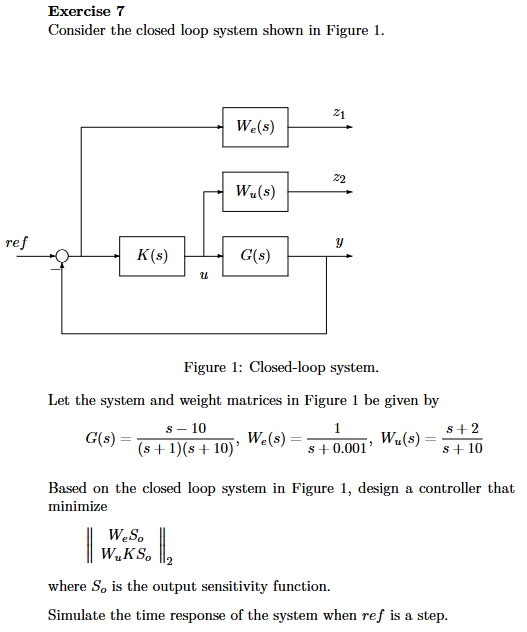

% Get state space models from transfer functions
w = logspace(-2, 4, 100);
[A,B,C,D] = tf2ss([1 -10], [1 11 10]);
[Ae,Be,Ce,De] = tf2ss([1], [1 0.001]);
[Au,Bu,Cu,Du] = tf2ss([1 2], [1 10]);

G = ss(A,B,C,D);
We = ss(Ae,Be,Ce,De);
Wu = ss(Au,Bu,Cu,Du);

% Set up P
G.InputName = "u"; G.OutputName = "y";
Wu.InputName = "u"; Wu.OutputName = "z2";
We.InputName = "e"; We.OutputName = "z1";
S1 = sumblk("e = ref - y");

P = connect(G, We, Wu, S1, {"ref", "u"}, {"z1", "z2", "e"});

% H2 controller design
[K, CL, gamma] = h2syn(P, 1, 1);
display(gamma) % gamma being the H2 norm

gamma = 1.0627

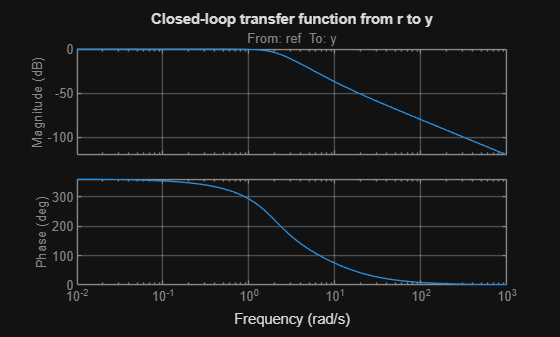


% Calculation of closed-loop without weight functions
% Assume G and k2 are already defined as ss models

% Assign input/output names
G.InputName = "u";    % input to G is u
G.OutputName = "y";   % output of G is y

K.InputName = "e";   % input to k2 is error signal e
K.OutputName = "u";  % output of k2 is control u

% Define the error signal: e = dist1 - y
S2 = sumblk("e = ref - y");

% Connect the system
P_cl = connect(G, K, S2, "ref", "y");  % input: dist1, output: y

figure(1)
bode(P_cl)
grid on
title('Closed-loop transfer function from r to y')

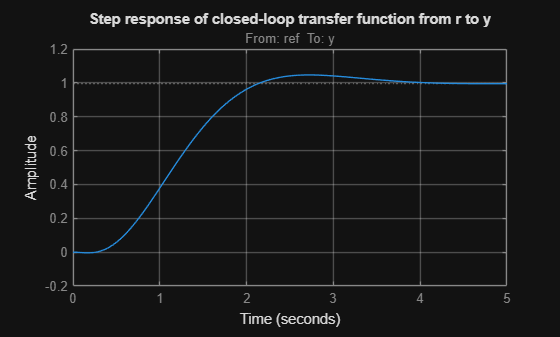

figure(2)
step(P_cl)
grid on
title('Step response of closed-loop transfer function from r to y')

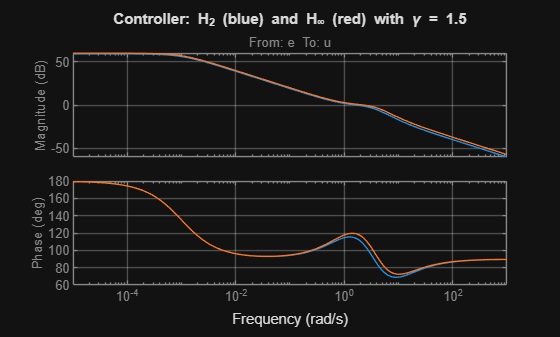

% Controller design using mixsyn from H_infinity design
% Use gamma = 1.5 and 10
G = ss(A,B,C,D);
We = ss(Ae,Be,Ce,De);
Wu = ss(Au,Bu,Cu,Du);
Wy = [];
g0 = 1.5;
[K2,CL1,gamma1] = mixsyn(G, We, Wu, Wy, g0);
g1 = 10;
[K3,CL2,gamma2] = mixsyn(G, We, Wu, Wy, g1);

figure(3)
bode(K, K2)
grid on
title('Controller: H_2 (blue) and H_{\infty} (red) with \gamma = 1.5')

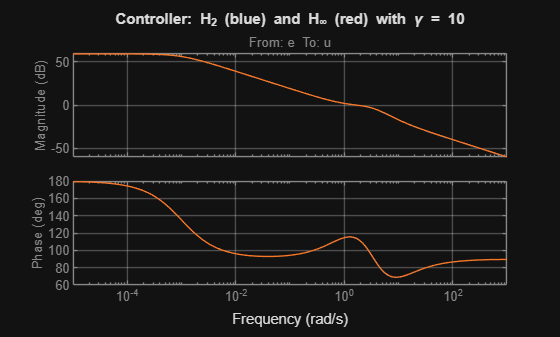

legend on
figure(4)
bode(K, K3)
grid on
title('Controller: H_2 (blue) and H_{\infty} (red) with \gamma = 10')

legend on

## Exercise 8

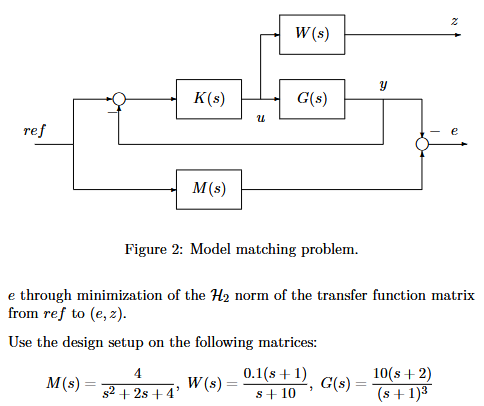

% Set up state space models
w = logspace(-2,4,100);
[AM,BM,CM,DM] = tf2ss([4], [1 2 4]);
[AW,BW,CW,DW] = tf2ss([0.1 0.1], [1 10]);
[AG,BG,CG,DG] = tf2ss([10 20], [1 3 3 1]);

M = ss(AM,BM,CM,DM);
W = ss(AW,BW,CW,DW);
G = ss(AG,BG,CG,DG);

% Set up P
G.InputName = "u"; G.OutputName = "y";
W.InputName = "u"; W.OutputName = "z";
M.InputName = "ref"; M.OutputName = "ym";
S1 = sumblk("e1 = ym - y");
S2 = sumblk("e2 = ref - y");

P = connect(G, W, M, S1, S2, {"ref", "u"}, {"z", "e1", "e2"});

% H2 controller design
[K, CL, gamma] = h2syn(P, 1, 1);
display(gamma) % gamma being the H2 norm

gamma = 0.1141

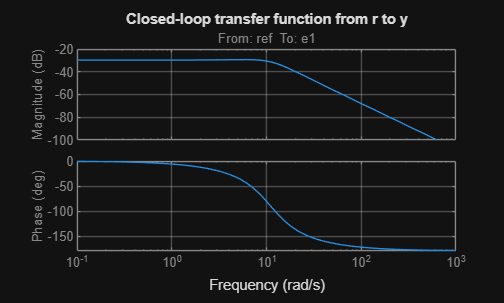

% Calculation of closed-loop without weight functions
% Assume G and k2 are already defined as ss models

% Assign input/output names
G.InputName = "u"; G.OutputName = "y";

M.InputName = "ref"; M.OutputName = "ym";

S1 = sumblk("e1 = ym - y");
S2 = sumblk("e2 = ref - y");

K.InputName = "e2";   % input to k2 is error signal e
K.OutputName = "u";  % output of k2 is control u

% Connect the system
P_cl = connect(G, K, M, S1, S2, "ref", "e1");  % input: dist1, output: y

figure(1)
bode(P_cl)
grid on
title('Closed-loop transfer function from r to y')

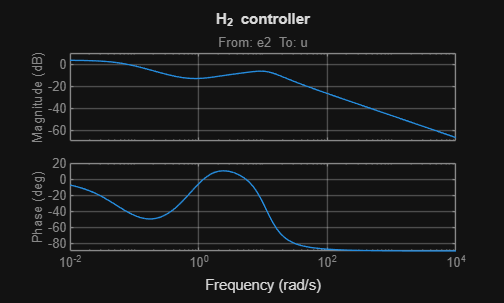

figure(2)
bode(K,w)
grid on
title('H_2 controller')

## Exercsie 9

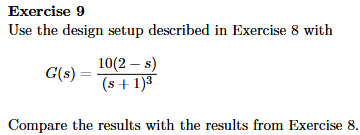

% Set up state space models
w = logspace(-2,4,100);
[AM,BM,CM,DM] = tf2ss([4], [1 2 4]);
[AW,BW,CW,DW] = tf2ss([0.1 0.1], [1 10]);
[AG,BG,CG,DG] = tf2ss([-10 20], [1 3 3 1]);

M = ss(AM,BM,CM,DM);
W = ss(AW,BW,CW,DW);
G = ss(AG,BG,CG,DG);

% Set up P
G.InputName = "u"; G.OutputName = "y";
W.InputName = "u"; W.OutputName = "z";
M.InputName = "ref"; M.OutputName = "ym";
S1 = sumblk("e1 = ym - y"); S2 = sumblk("e2 = ref - y");

P = connect(G, W, M, S1, S2, {"ref", "u"}, {"z", "e1", "e2"});

% H2 controller design
[K1, CL, gamma] = h2syn(P, 1, 1);
display(gamma) % gamma being the H2 norm

gamma = 0.8037

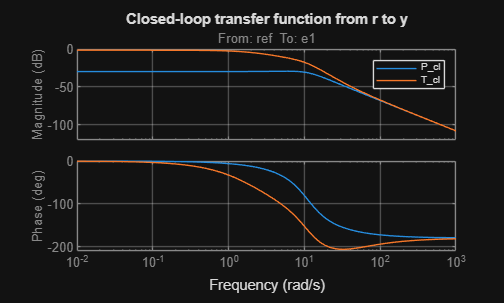

% Calculation of closed-loop without weight functions
% Assume G and k2 are already defined as ss models

% Assign input/output names
G.InputName = "u"; G.OutputName = "y";

M.InputName = "ref"; M.OutputName = "ym";

S1 = sumblk("e1 = ym - y");
S2 = sumblk("e2 = ref - y");

K1.InputName = "e2";   % input to k2 is error signal e
K1.OutputName = "u";  % output of k2 is control u

% Connect the system
T_cl = connect(G, K1, M, S1, S2, "ref", "e1");  % input: dist1, output: y

figure(1)
bode(P_cl, T_cl)
grid on
title('Closed-loop transfer function from r to y')
legend on

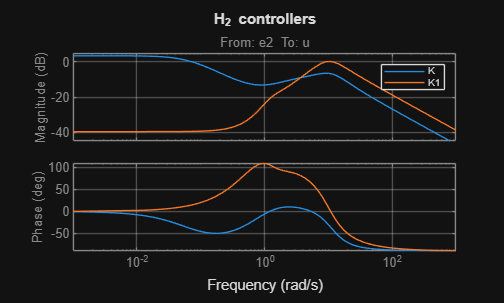

figure(2)
bode(K, K1)
grid on
title('H_2 controllers')
legend on

## Exercise 10

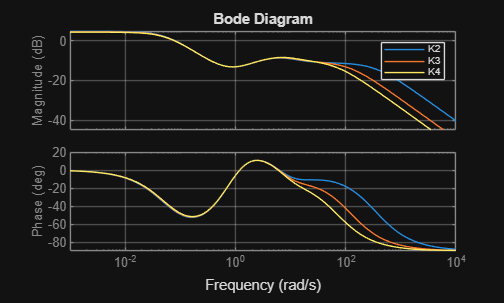

% Controller design using mixsyn from H_infinity design
% Use gamma = 1.01, 1.05 and 1.1
w = logspace(-2,4,100);
[A,B,C,D] = tf2ss([10 20],[1 3 3 1]);
[AW,BW,CW,DW] = tf2ss([0.1 0.1],[1 10]);
[AM,BM,CM,DM] = tf2ss([4],[1 2 4]);

G = ss(A,B,C,D);
W = ss(AW,BW,CW,DW);
M = ss(AM,BM,CM,DM);

% Set up P
G.InputName = "u"; G.OutputName = "y";
W.InputName = "u"; W.OutputName = "z";
M.InputName = "ref"; M.OutputName = "ym";
S1 = sumblk("e1 = ym - y");
S2 = sumblk("e2 = ref - y");

P = connect(G, W, M, S1, S2, {"ref", "u"}, {"z", "e1", "e2"});

% H inf controller design
[K, CL, gamma] = hinfsyn(P, 1, 1);

g01 = gamma*1.01; g05 = gamma*1.05; g1 = gamma*1.1;

[K2,CL2,gamma2] = hinfsyn(P, 1, 1, g01);
[K3,CL3,gamma3] = hinfsyn(P, 1, 1, g05);
[K4,CL4,gamma4] = hinfsyn(P, 1, 1, g1);

figure(3)
bode(K2, K3, K4)
grid on
legend on